
clc;
clear;
close all;

y[n]=x[n]-x[n-1];

y[n]=y[n-1]+x[n];

y[n]=1/3*(x[n]+x[n-1]+x[n-2]);

y[n]=0.8*y[n-1]+0.2x[n];

y[n]=y[n-1]+1/3*(x[n]-x[n-3]);

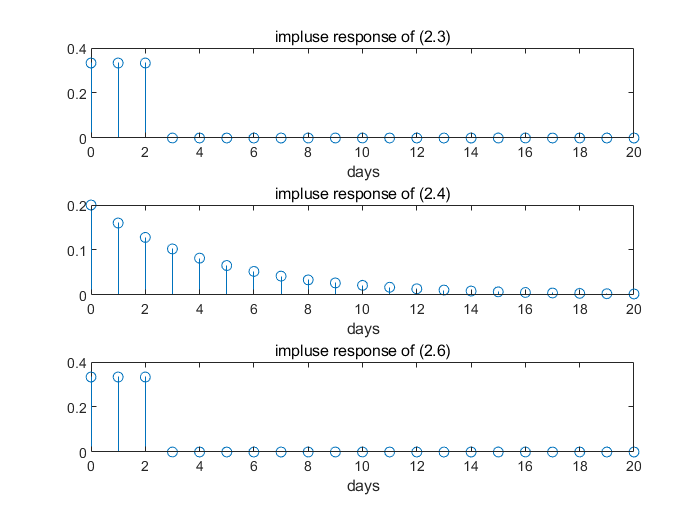

n=0:20;
%unit impulse function
delta_n=(n==0);
y1=f2_3(delta_n);
y2=f2_4(delta_n);
y3=f2_5(delta_n);
%get the impulse response
figure
subplot(3,1,1)
stem(n,y1),title('impluse response of (2.3)'),xlabel('days')
subplot(3,1,2)
stem(n,y2),title('impluse response of (2.4)'),xlabel('days')
subplot(3,1,3)
stem(n,y3),title('impluse response of (2.6)'),xlabel('days')